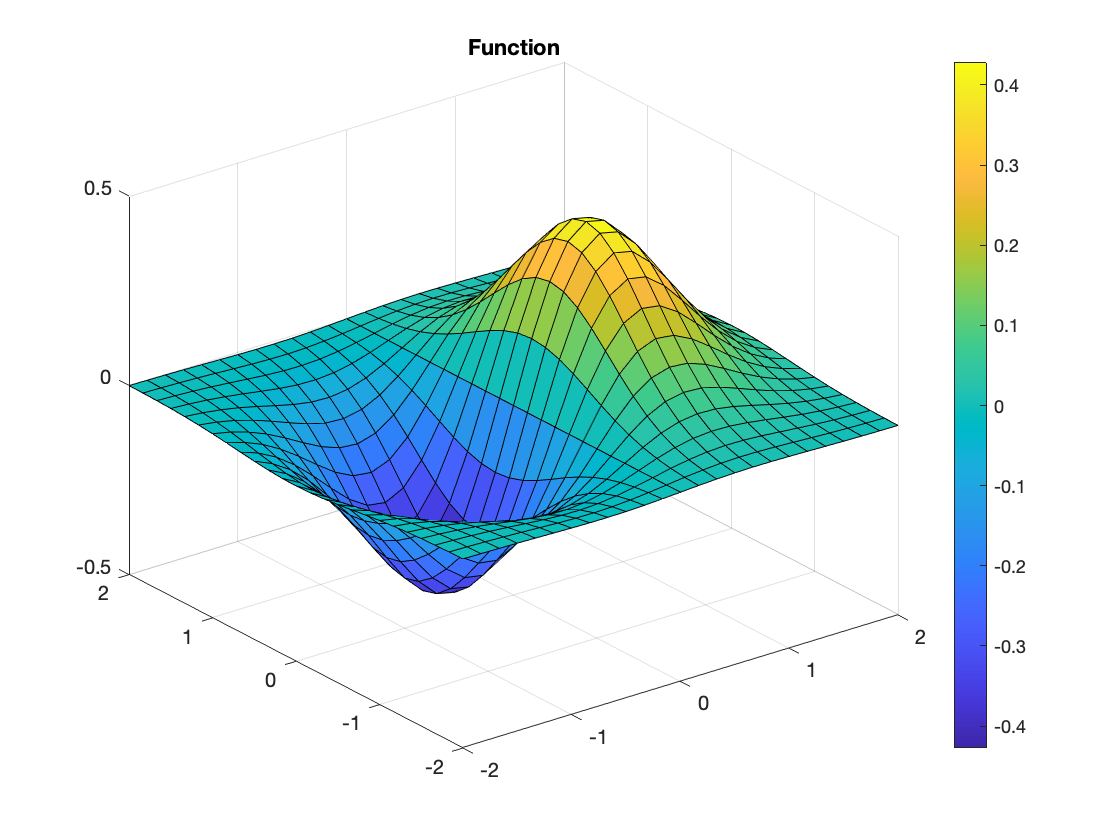

x=linspace(-2, 2, 25);
y=linspace(-2, 2, 25);
[xx, yy]=meshgrid(x, y);
zz=xx.*exp(-xx.^2 - yy.^2);
figure
surf(xx,yy,zz);
colorbar
title 'Function'

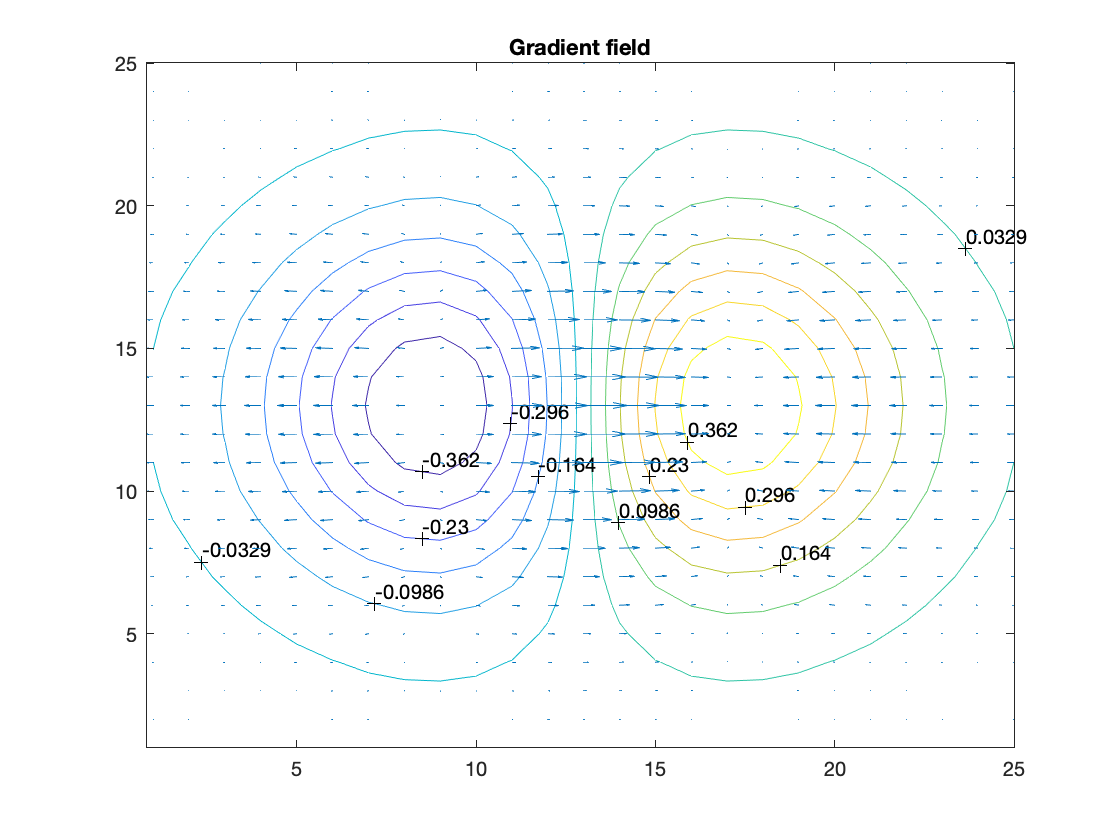

x=linspace(-2, 2, 25);
y=linspace(-2, 2, 25);
[xx, yy]=meshgrid(x, y);
zz=xx.*exp(-xx.^2 - yy.^2);
figure
h=contour(zz, 12);
clabel(h);
[dx, dy]=gradient(zz,.2,2);
hold on;
quiver(dx, dy);
title 'Gradient field'